% a04_p2_scatter_plot_fitting_v4.mlx

clear all; close all; clc;

% set data path
currentDir = pwd;
exptDir = currentDir(1:regexp(pwd,'03ExpCode')-1);
addpath(genpath([exptDir '03ExpCode/01pretest/data']));
addpath(genpath([exptDir '03ExpCode/04posttest/data']));

% define subjects and sessions
all_sub = [3,4,6:10];
n_sub = numel(all_sub);
n_all_sub = all_sub(end);
all_sess = 1:9;
n_sess = numel(all_sess);

% load model comparison/fitting results
load('a04_v4_mc_results.mat')

% fixed parameter
fix_lambda = 0.3;

% define x-grid to be eval
[pre_ms_unique, post_ms_unique] = deal([-500, -300:50:300, 500]);

% define PMF
P_Afirst                      = @(SOA, mu, sig, c, lambda) lambda/3 + (1-lambda).*normcdf(-c, SOA - mu, sig);
P_Vfirst                      = @(SOA, mu, sig, c, lambda) lambda/3 + (1-lambda).*(1 - normcdf(c, SOA-mu, sig));
P_simultaneous                = @(SOA, mu, sig, c, lambda) ...
    1 - (lambda/3 + (1-lambda).*normcdf(-c, SOA - mu, sig)) ...
    - (lambda/3 + (1-lambda).*(1 - normcdf(c, SOA-mu, sig)));

% define model
M1 = {@(p) P_Vfirst(pre_ms_unique, p(1), p(3), p(5), fix_lambda);...
    @(p) P_simultaneous(pre_ms_unique, p(1), p(3), p(5), fix_lambda);...
    @(p) P_Afirst(pre_ms_unique, p(1), p(3), p(5), fix_lambda);...
    @(p) P_Vfirst(post_ms_unique, p(2), p(4), p(6), fix_lambda);...
    @(p) P_simultaneous(post_ms_unique, p(2), p(4), p(6), fix_lambda);...
    @(p) P_Afirst(post_ms_unique, p(2), p(4), p(6), fix_lambda)};

M7 = {@(p) P_Vfirst(pre_ms_unique, p(1), p(3), p(4), fix_lambda);...
    @(p) P_simultaneous(pre_ms_unique, p(1), p(3), p(4), fix_lambda);...
    @(p) P_Afirst(pre_ms_unique, p(1), p(3), p(4), fix_lambda);...
    @(p) P_Vfirst(post_ms_unique, p(2), p(3), p(4), fix_lambda);...
    @(p) P_simultaneous(post_ms_unique, p(2), p(3), p(4), fix_lambda);...
    @(p) P_Afirst(post_ms_unique, p(2), p(3), p(4), fix_lambda)};

M8 = {@(p) P_Vfirst(pre_ms_unique, p(1), p(3), p(5), fix_lambda);...
    @(p) P_simultaneous(pre_ms_unique, p(1), p(3), p(5), fix_lambda);...
    @(p) P_Afirst(pre_ms_unique, p(1), p(3), p(5), fix_lambda);...
    @(p) P_Vfirst(post_ms_unique, p(2), p(4), p(6), fix_lambda);...
    @(p) P_simultaneous(post_ms_unique, p(2), p(4), p(6), fix_lambda);...
    @(p) P_Afirst(post_ms_unique, p(2), p(4), p(6), fix_lambda)};

% pre-allocate, each cell has the size (number of all subjects x number of
% sessions), within each cell is a matrix of number of response conditions
% (1:3: pre, 4:6: post) x percentage of responses in each condition (15 levels).
% Note that pResp_data and pResp_fit has different order of conditions
[pResp_data, pResp_M1_fit, pResp_M7_fit, pResp_M8_fit] = deal(cell(n_all_sub, n_sess));

for sub = all_sub

    for s = all_sess % loop by session, but plot by adaptor SOA

        %%%%%%%%%%%% 1) p(a-first), p(v-first) from raw data

        %%%%% pre-test
        load(['pretest_sub' num2str(sub) '_session' num2str(s) '.mat'])
        pre_s_unique                               = ExpInfo.SOA; % unique SOA levels, in s
        pre_ms_unique                              = pre_s_unique * 1e3; % unique SOA levels, in ms
        pre_numTrials                              = ExpInfo.nTrials; % num of trials per SOA
        % inititate
        pre_r_org                                  = NaN(length(pre_s_unique), pre_numTrials);
        pre_respCount                              = NaN(3, length(pre_s_unique));
        for i                                      = 1:length(pre_s_unique)
            iSOA                                       = pre_s_unique(i);
            iResp                                      = Response.order(ExpInfo.trialSOA == iSOA);
            pre_r_org(i,:)                             = iResp; % this matrix has a size of length(s_unique) x numTrials
            for j                                      = unique(Response.order) % 1 = V first, 2 = simultaneous, 3 = A first
                pre_respCount(j,i)                         = sum(iResp == j);
            end
        end

        %%%%% post-test
        % load data and define key parameters
        load(['posttest_sub' num2str(sub) '_session' num2str(s) '.mat'])
        post_s_unique                              = ExpInfo.SOA; % unique SOA levels, in ms
        post_ms_unique                             = post_s_unique * 1e3; % unique SOA levels, in s
        post_numTrials                             = ExpInfo.nTrials; % num of trials per SOA
        % inititate
        post_r_org                                 = NaN(length(post_s_unique), post_numTrials);
        post_respCount                             = NaN(3, length(post_s_unique));
        for i                                      = 1:length(post_s_unique)
            iSOA                                       = post_s_unique(i);
            iResp                                      = Response.order(ExpInfo.trialSOA == iSOA);
            post_r_org(i,:)                            = iResp; % this matrix has a size of length(s_unique) x numTrials
            for j                                      = unique(Response.order) % 1 = V first, 2 = simultaneous, 3 = A first
                post_respCount(j,i)                        = sum(iResp == j);
            end
        end

        % matrix on the right: each row is the percentage of response at
        % each SOA level, where row indicates:
        % 1 = pre-V, 2 = pre-simul, 3 = pre-A,
        % 4 = post-V, 5 = post-simul, 6 = post-A
        pResp_data{sub, s}                   = [pre_respCount/pre_numTrials; post_respCount/post_numTrials];


        %%%%%%%%%%%% 2)p(a-first_M1_fit), p(v-first_M1_fit) from the
        % fitting of the full model (M1);

        % extract M1 best-fitting parameters
        M1_para = estP.M1_to_6{sub}{s,1};

        % matrix on the right: each row is the percentage of response at
        % each SOA level, where row indicates:
        % 1 = pre-V, 2 = pre-simul, 3 = pre-A,
        % 4 = post-V, 5 = post-simul, 6 = post-A
        pResp_M1_fit{sub, s} = arrayfun(@(c) M1{c}(M1_para), 1:6, 'UniformOutput', false);

        %%%%%%%%%%%% 3)p(a-first_M7_fit), p(v-first_M7_fit) from the

        % fitting of the reduced model (M7);
        M7_para = estP.M7_to_8{sub}{1,1};

        % extract the specific parameter for this session
        M7_para_sess = [M7_para(1), M7_para(s+1), M7_para(11), M7_para(12)];

        % matrix on the right: each row is the percentage of response at
        % each SOA level, where row indicates:
        % 1 = pre-V, 2 = pre-simul, 3 = pre-A,
        % 4 = post-V, 5 = post-simul, 6 = post-A
        pResp_M7_fit{sub, s} = arrayfun(@(c) M7{c}(M7_para_sess), 1:6, 'UniformOutput', false);

        %%%%%%%%%%%% 4)p(a-first_M8_fit), p(v-first_M8_fit) from the

        % fitting of the reduced model (M8);
        M8_para = estP.M7_to_8{sub}{1,2};

        % extract the specific parameter for this session
        M8_para_sess = [M8_para(1), M8_para(s+1), M8_para(11), M8_para(12), M8_para(13), M8_para(14)];

        % matrix on the right: each row is the percentage of response at
        % each SOA level, where row indicates:
        % 1 = pre-V, 2 = pre-simul, 3 = pre-A,
        % 4 = post-V, 5 = post-simul, 6 = post-A
        pResp_M8_fit{sub, s} = arrayfun(@(c) M8{c}(M8_para_sess), 1:6, 'UniformOutput', false);

    end
end

## scatter plots to compare fits by two models

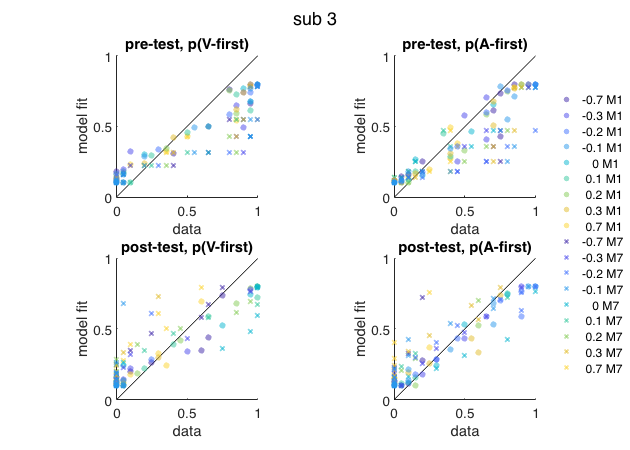

close all;
% for each participant
% extract adaptor condition to loop adaptor
addpath(genpath([exptDir '03ExpCode/05functions']));

load('RandomAdaptorOrder.mat')
cmap = parula;
cidx = floor(linspace(1,230,n_sess));

for sub = all_sub

    i_adaptor_soa = randomAdaptorOrder(sub,:);
    [sorted_adaptor_soa, order] = sort(i_adaptor_soa);

    figure; hold on
    sgtitle(['sub ' num2str(sub)], 'FontSize', 20)
    set(gcf,'position',[0 0 700 500]);


    %% plot for pre-test, V-first responses
    subplot(2,2,1); set(gca, 'LineWidth', 1, 'FontSize', 15); hold on
    title('pre-test, p(V-first)')
    xlabel('data'); ylabel('model fit');
    line; axis square

    for s = order
        i_v_first_data = pResp_data{sub, s}(1,:);
        i_v_first_M1_fit = pResp_M1_fit{sub, s}{1};
        i_v_first_M7_fit = pResp_M7_fit{sub, s}{1};
        scatter(i_v_first_data, i_v_first_M1_fit, 50, 'o','MarkerFaceColor',cmap(cidx(s),:), 'MarkerEdgeColor','none','MarkerFaceAlpha', 0.5)
        %         scatter(i_v_first_data, i_v_first_M7_fit, 50, '^','MarkerFaceColor',cmap(cidx(s),:), 'MarkerEdgeColor','none','MarkerFaceAlpha', 0.5)
        scatter(i_v_first_data, i_v_first_M7_fit, 50, 'x','MarkerEdgeColor',cmap(cidx(s),:), 'LineWidth', 2, 'MarkerEdgeAlpha', 0.5)
    end


    %% plot for pre-test, A-first responses
    subplot(2,2,2); set(gca, 'LineWidth', 1, 'FontSize', 15); hold on
    title('pre-test, p(A-first)')
    xlabel('data'); ylabel('model fit');
    line; axis square

    for s = order
        i_v_first_data = pResp_data{sub, s}(3,:);
        i_v_first_M1_fit = pResp_M1_fit{sub, s}{3};
        i_v_first_M7_fit = pResp_M7_fit{sub, s}{3};
        scatter(i_v_first_data, i_v_first_M1_fit, 50, 'o','MarkerFaceColor',cmap(cidx(s),:), 'MarkerEdgeColor','none','MarkerFaceAlpha', 0.5)
        scatter(i_v_first_data, i_v_first_M7_fit, 50, 'x','MarkerEdgeColor',cmap(cidx(s),:), 'LineWidth', 2, 'MarkerEdgeAlpha', 0.5)
    end

    %% plot for post-test, V-first responses
    subplot(2,2,3); set(gca, 'LineWidth', 1, 'FontSize', 15); hold on
    title('post-test, p(V-first)')
    xlabel('data'); ylabel('model fit');
    line; axis square

    for s = order
        i_v_first_data = pResp_data{sub, s}(4,:);
        i_v_first_M1_fit = pResp_M1_fit{sub, s}{4};
        i_v_first_M7_fit = pResp_M7_fit{sub, s}{4};
        scatter(i_v_first_data, i_v_first_M1_fit, 50, 'o','MarkerFaceColor',cmap(cidx(s),:), 'MarkerEdgeColor','none','MarkerFaceAlpha', 0.5)
        scatter(i_v_first_data, i_v_first_M7_fit, 50, 'x','MarkerEdgeColor',cmap(cidx(s),:), 'LineWidth', 2, 'MarkerEdgeAlpha', 0.5)
    end

    %% plot for post-test, A-first responses
    subplot(2,2,4); set(gca, 'LineWidth', 1, 'FontSize', 15); hold on
    title('post-test, p(A-first)')
    xlabel('data'); ylabel('model fit');
    line; axis square

    for s = order
        i_v_first_data = pResp_data{sub, s}(6,:);
        i_v_first_M1_fit = pResp_M1_fit{sub, s}{6};
        i_v_first_M7_fit = pResp_M7_fit{sub, s}{6};
        l_M1(s) = scatter(i_v_first_data, i_v_first_M1_fit, 50, 'o','MarkerFaceColor',cmap(cidx(s),:), 'MarkerEdgeColor','none','MarkerFaceAlpha', 0.5);
        l_M7(s) = scatter(i_v_first_data, i_v_first_M7_fit, 50, 'x','MarkerEdgeColor',cmap(cidx(s),:), 'LineWidth', 2, 'MarkerEdgeAlpha', 0.5);
    end

    labels = split(num2str(sorted_adaptor_soa),'        ');
    labels_M1 = strcat(labels,' M1');
    labels_M7 = strcat(labels,' M7');

    hl = legend([l_M1, l_M7], [labels_M1; labels_M7]);
    legend boxoff
    set(hl,'Position',[0.87052,0.1623,0.12714,0.637])

end

## scatter plot of all subjects for only one model

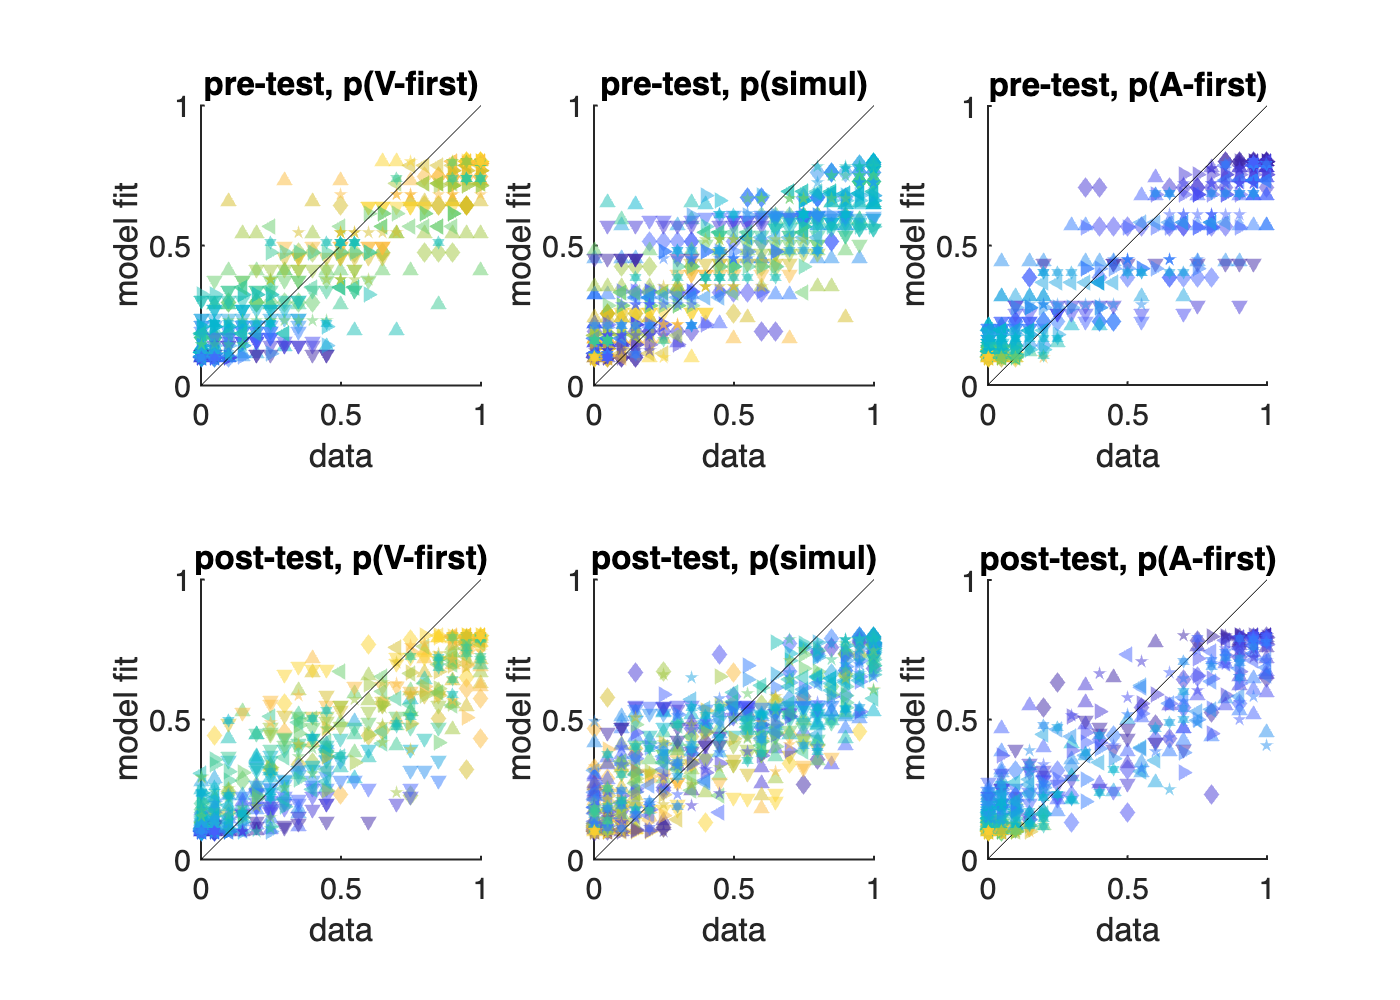

close all;

% set plotting parameters
test_soa = pre_ms_unique;
n_test_soa = numel(test_soa);
% color code: test SOA (15 levels)
cmap = parula;
cidx = floor(linspace(1,230,n_test_soa));
% marker: subject
markers = ['o','s','d','^','v','>','<','p','*','h'];
condTitle = {'pre-test, p(V-first)','pre-test, p(simul)','pre-test, p(A-first)',...
    'post-test, p(V-first)','post-test, p(simul)','post-test, p(A-first)'};
labels = split(sprintf('%d ',test_soa),' ');

% initiate figure
figure; hold on
set(gcf,'position',[0 0 700 500]);

for sub = all_sub
    for c = 1:6
        subplot(2,3,c); set(gca, 'LineWidth', 1, 'FontSize', 15); hold on
        line; axis square
        title(condTitle{c})
        xlabel('data'); ylabel('model fit');

        for s = 1:n_sess

            for t = 1:n_test_soa
                i_v_first_data = pResp_data{sub, s}(c,t);
                i_v_first_M1_fit = pResp_M1_fit{sub, s}{c}(t);
                i_v_first_M8_fit = pResp_M8_fit{sub, s}{c}(t);
                scatter(i_v_first_data, i_v_first_M8_fit, 50, markers(sub),'MarkerFaceColor',cmap(cidx(t),:), 'MarkerEdgeColor','none','MarkerFaceAlpha', 0.5);
            end
        end

    end
end



% leg = legend(l, labels);
% legend boxoff
% %             set(hl,'Position','bestoutside')
% title(leg,'test SOA')
